g1 = [0.1; 1.1];
g2 = [0.5; 1];
delta = g1 - g2;

theta1 = 0.02*pi + pi/2;
theta2 = theta1 + 3*pi/2;
m1 = [cos(theta1), -sin(theta1); sin(theta1), cos(theta1)]*delta;
m2 = [cos(theta2), -sin(theta2); sin(theta2), cos(theta2)]*delta;
U = [m1, m2];

tau_1 = [-0.1, -1];
tau_2 = [-1, -0.1];

M1 = U*diag(tau_1)*U';
M2 = U*diag(tau_2)*U';

g = g2;
M = M1;

[x1, x2] = meshgrid(5:0.5:25, 80:0.5:100);
x1dot = M(1,1)*x1 + M(1,2)*x2 + g(1);
x2dot = M(2,1)*x1 + M(2,2)*x2 + g(2);

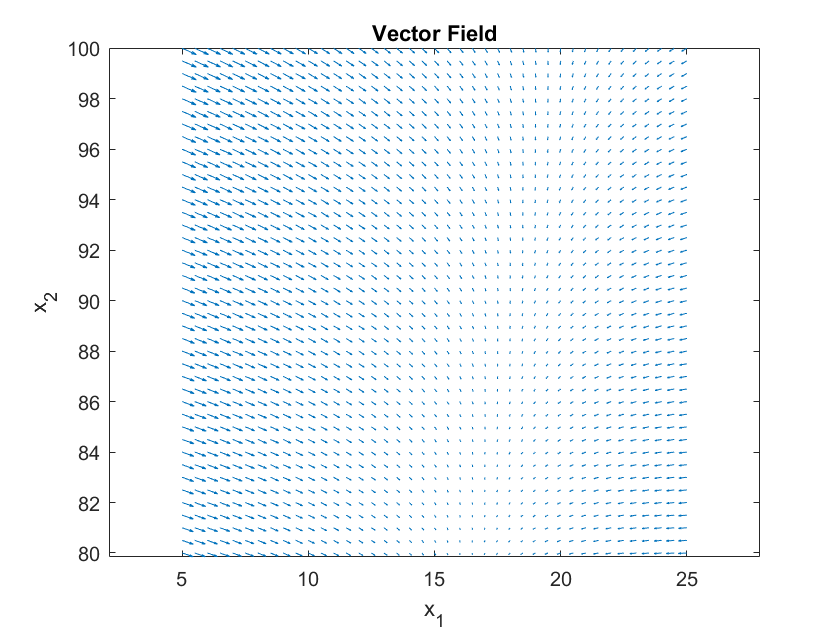

figure;
quiver(x1, x2, x1dot, x2dot, 'DisplayName', 'Vector Field');
xlabel('x_1');
ylabel('x_2');
title('Vector Field');
axis equal;

x0 = [16; 75];
dt = 0.2;

% Convergence criteria
tolerance = 1e-6;
max_iterations = 5000;

% Forward Euler simulation
xg1 = x0;
xg2 = x0;
iterations = 0;

x_trajectory11 = xg1;
x_trajectory12 = xg2;

while true
    % Euler step
    xg1_next = xg1 + dt * (M1 * xg1 + g1);
    xg2_next = xg2 + dt * (M1 * xg2 + g2);
    
    % Check for convergence
    if ((norm(xg1_next - xg1) < tolerance) && (norm(xg2_next - xg2) < tolerance)) || iterations >= max_iterations
        break;
    end
    
    % Update state
    xg1 = xg1_next;
    xg2 = xg2_next;
    x_trajectory11 = [x_trajectory11, xg1];
    x_trajectory12 = [x_trajectory12, xg2];
    
    iterations = iterations + 1;
end

disp(['Converged after ', num2str(iterations), ' iterations']);

Converged after 3152 iterations


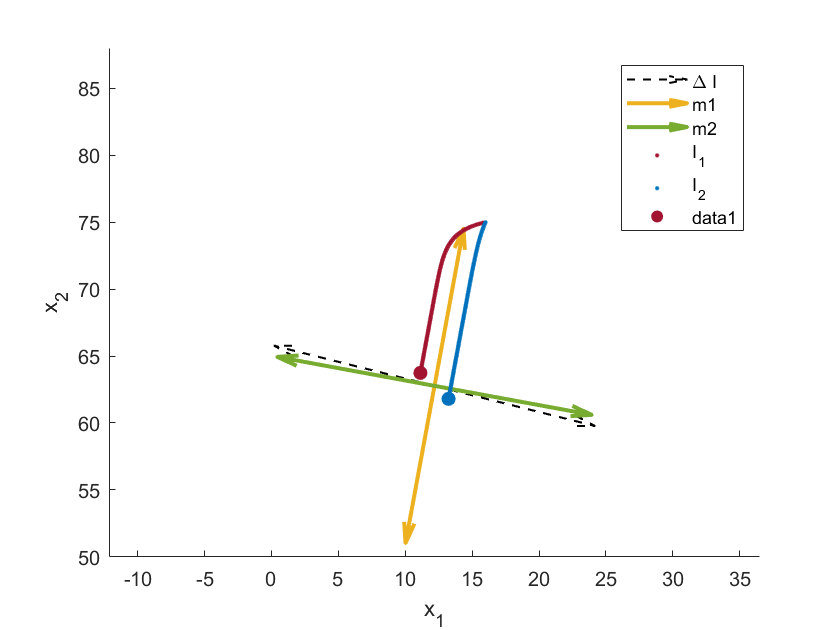

% Plot the original and smoothed trajectories
figure;
hold on

sc = 30;
sm = 29;
t = (x_trajectory11(:,end) + x_trajectory12(:,end)) / 2;
quiver([t(1), t(1)], [t(2), t(2)], [-delta(1)*sc, delta(1)*sc], [-delta(2)*sc, delta(2)*sc],"off", ...
    'k--', 'Linewidth',1, 'DisplayName', '\Delta I');
quiver([t(1), t(1)], [t(2), t(2)], [-m1(1)*sm, m1(1)*sm], [-m1(2)*sm, m1(2)*sm],"off", ...
    '-', 'Linewidth',2,'Color','#EDB120','DisplayName', 'm1');
quiver([t(1), t(1)], [t(2), t(2)], [-m2(1)*sm, m2(1)*sm], [-m2(2)*sm, m2(2)*sm],"off", ...
    '-', 'Linewidth',2,'Color',"#77AC30",'DisplayName', 'm2');

plot(x_trajectory11(1, :), x_trajectory11(2, :), '.','Color','#A2142F','DisplayName', 'I_1');
plot(x_trajectory12(1, :), x_trajectory12(2, :), '.','Color',"#0072BD",'DisplayName', 'I_2');
scatter([x_trajectory11(1, end), x_trajectory12(1, end)], [x_trajectory11(2, end), x_trajectory12(2, end)], ...
    50, [0.6350 0.0780 0.1840; 0 0.4470 0.7410], 'filled','o');
legend;
xlabel('x_1');
ylabel('x_2');

ylim([50, 88])
axis equal

% perturbation
r_ss = x_trajectory12(:, end);
per = [-20; 104];
r_per = nan(2, 301);
r_per(:, 1) = r_ss;
for t=1:300
    r_per(:, t+1) = expm(M1*t)*per + r_ss;
end
r_per_p = U'*r_per

r_per_p =   -26.0491  -66.0407  -65.3665  -64.7038  -64.0522  -63.4116  -62.7818  -62.1627  -61.5539  -60.9554  -60.3670  -59.7886  -59.2198  -58.6607  -58.1110  -57.5706  -57.0392  -56.5168  -56.0033  -55.4984  -55.0019  -54.5139  -54.0341  -53.5624  -53.0986  -52.6426  -52.1944  -51.7537  -51.3204  -50.8944  -50.4756  -50.0639  -49.6591  -49.2611  -48.8698  -48.4851  -48.1070  -47.7351  -47.3696  -47.0102  -46.6569  -46.3095  -45.9680  -45.6322  -45.3021  -44.9776  -44.6585  -44.3449  -44.0365  -43.7333
   -0.7533   12.6417   10.5476    8.7809    7.2904    6.0329    4.9719    4.0769    3.3218    2.6847    2.1472    1.6938    1.3112    0.9885    0.7162    0.4864    0.2926    0.1291   -0.0088   -0.1252   -0.2234   -0.3062   -0.3761   -0.4351   -0.4848   -0.5268   -0.5622   -0.5921   -0.6173   -0.6385   -0.6565   -0.6716   -0.6844   -0.6952   -0.7042   -0.7119   -0.7184   -0.7238   -0.7284   -0.7323   -0.7356   -0.7384   -0.7407   -0.7427   -0.7443   -0.7457   -0.7469   -0.7479   -0.748

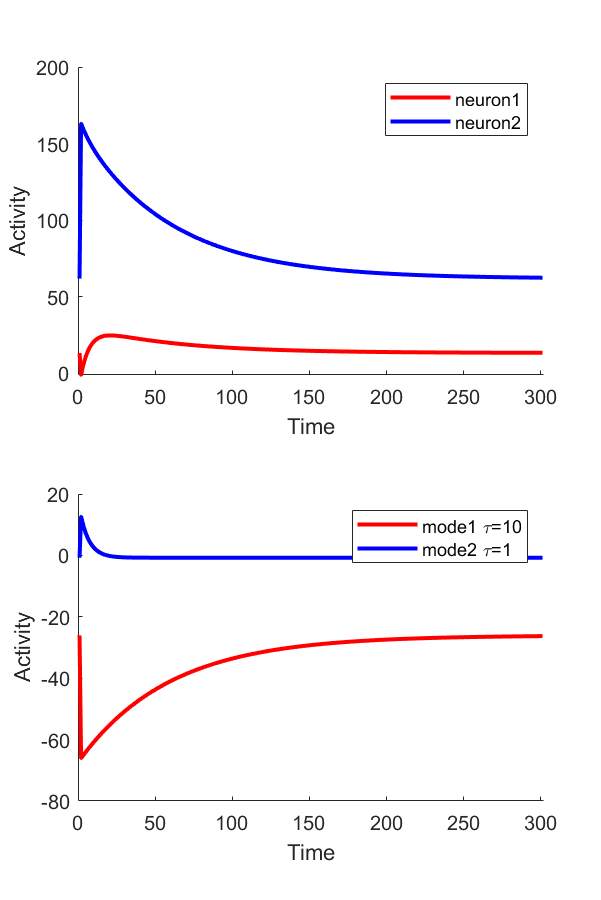


figure('Position', [0 0 400 600])
subplot(2, 1, 1);
hold on
plot(r_per(1, :), 'r-','Linewidth',2,'DisplayName', 'neuron1');
plot(r_per(2, :), 'b-','Linewidth',2,'DisplayName', 'neuron2');
xlim([0, 302]);
legend;
xlabel('Time');
ylabel('Activity');

subplot(2, 1, 2);
hold on
plot(r_per_p(1, :), 'r-','Linewidth',2,'DisplayName', 'mode1 \tau=10');
plot(r_per_p(2, :), 'b-','Linewidth',2,'DisplayName', 'mode2 \tau=1');
xlim([0, 302]);
legend;
xlabel('Time');
ylabel('Activity');

x0 = [10; 17];
dt = 0.2;

% Convergence criteria
tolerance = 1e-6;
max_iterations = 5000;

% Forward Euler simulation
xg1 = x0;
xg2 = x0;
iterations = 0;

x_trajectory11 = xg1;
x_trajectory12 = xg2;

while true
    % Euler step
    xg1_next = xg1 + dt * (M2 * xg1 + g1);
    xg2_next = xg2 + dt * (M2 * xg2 + g2);
    
    % Check for convergence
    if ((norm(xg1_next - xg1) < tolerance) && (norm(xg2_next - xg2) < tolerance)) || iterations >= max_iterations
        break;
    end
    
    % Update state
    xg1 = xg1_next;
    xg2 = xg2_next;
    x_trajectory11 = [x_trajectory11, xg1];
    x_trajectory12 = [x_trajectory12, xg2];
    
    iterations = iterations + 1;
end

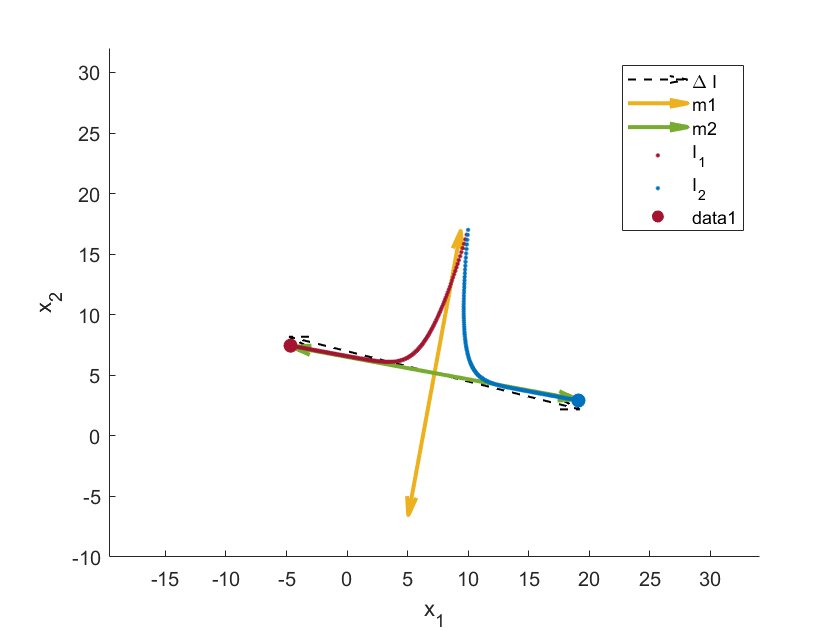

% Plot the original and smoothed trajectories
figure;
hold on

sc = 30;
sm = 29;
t = (x_trajectory11(:,end) + x_trajectory12(:,end)) / 2;
quiver([t(1), t(1)], [t(2), t(2)], [-delta(1)*sc, delta(1)*sc], [-delta(2)*sc, delta(2)*sc],"off", ...
    'k--', 'Linewidth',1, 'DisplayName', '\Delta I');
quiver([t(1), t(1)], [t(2), t(2)], [-m1(1)*sm, m1(1)*sm], [-m1(2)*sm, m1(2)*sm],"off", ...
    '-', 'Linewidth',2,'Color','#EDB120','DisplayName', 'm1');
quiver([t(1), t(1)], [t(2), t(2)], [-m2(1)*sm, m2(1)*sm], [-m2(2)*sm, m2(2)*sm],"off", ...
    '-', 'Linewidth',2,'Color',"#77AC30",'DisplayName', 'm2');

plot(x_trajectory11(1, :), x_trajectory11(2, :), '.','Color','#A2142F','DisplayName', 'I_1');
plot(x_trajectory12(1, :), x_trajectory12(2, :), '.','Color',"#0072BD",'DisplayName', 'I_2');
scatter([x_trajectory11(1, end), x_trajectory12(1, end)], [x_trajectory11(2, end), x_trajectory12(2, end)], ...
    50, [0.6350 0.0780 0.1840; 0 0.4470 0.7410], 'filled','o');
legend;
xlabel('x_1');
ylabel('x_2');

xlim([-5, 20])
ylim([-10, 32])
axis equal